## Introduction to HVES Battery Test Consortium

## Introduction

This live scrip explores the Melasta [SLPBB142124](https://github.com/HVES-Battery-Testing-Consortium/Melasta-SLPBB142124) cell test data provided by the Battery Test Consortium (BTC) [1]. The consortium is open source for Formula Student teams (signup [here](https://hves.brookes.ac.uk/btc/)) under the CC BY-NC-ND 4.0 license. We will look into the tests performed and how to make sense of this data. The details of the test and the equipment used can be found on the [Battery Testing Consortium Protocol](https://github.com/HVES-Battery-Testing-Consortium/Resources/blob/main/Protocols/BTC-Protocol-R1.pdf).

In this notebook, we will look into the following tests:

clear
addpath(genpath("data"));

POCV_GITT_file = "220504_BTC_POCV_GITT_Mel_SLPBB142124_1_25C_Channel_5_Wb_1";
HPPC_EIS_file = "221013_BTC_HPPC_EIS_Mel_SLPBB142124_1_25C_Channel_1_Wb_1";
static_capacity_file = "220504_BTC_StatCap_Mel_SLPBB142124_4_25C_Channel_3_Wb_1";
degradation_file = "221115_BTC_ENDUR_450V_Mel_SLPBB142124_7_30C_Channel_3_Wb_1";

## Pseudo Open Circuit Voltage (POCV)

Open Circuit Votlage is the voltage of the cell at rest (no load). This is function of state of charge (SOC) and temperature. Measuring OCV at the cell terminals at rest for several SOC and temperatures would be time consumin, so to accelerate this process, a cell is charged and discharged continously at very low current in a quasi-equilibrium state. This test is called pseudo-OCV, and was conducted on the BTC with a (dis)charge rate of 1/25C, which means the battery was completely (dis)charged in 25 hours.

The charge and discharge profiles will inevitably be different due to cell voltage hysteresis and because of the ohmic and diffusion polarization caused by the small current aplied in the test. However, this deviation can be considered symmetric and the final OCV can be found by the average of both charge and discharge tests. More on polarization can be found in [2], section 2.4.

Let's import the data to see how it looks like:

POCV_GITT_data = readtable(POCV_GITT_file, 'sheet', 'Channel-5_1', 'VariableNamingRule','preserve');

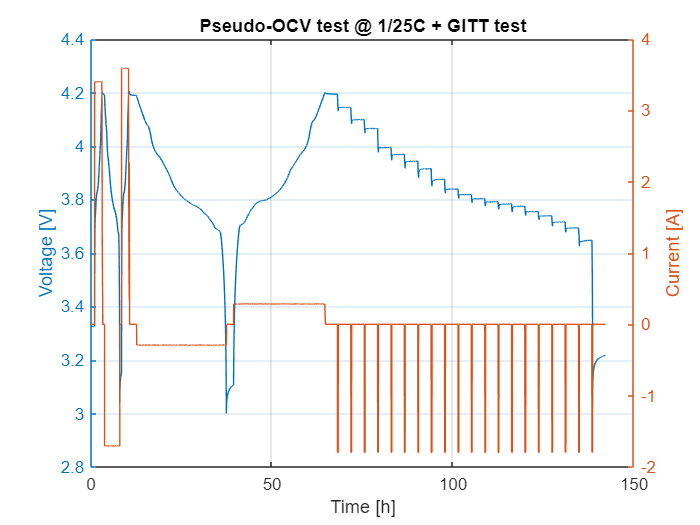

figure
yyaxis left
plot(POCV_GITT_data.("Test_Time(s)")./3600, POCV_GITT_data.("Voltage(V)"))
ylabel('Voltage [V]')
xlabel('Time [h]')
grid on
yyaxis right
plot(POCV_GITT_data.("Test_Time(s)")./3600, POCV_GITT_data.("Current(A)"))
title('Pseudo-OCV test @ 1/25C + GITT test')
ylabel('Current [A]')

This dataset has a counter (TC_Counter1) and step index channels to help the data postprocessing:

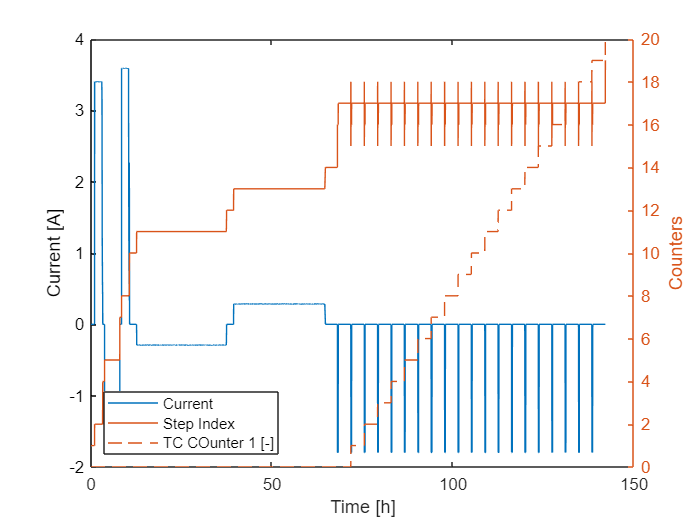

figure
grid on
plot(POCV_GITT_data.("Test_Time(s)")./3600, POCV_GITT_data.("Current(A)"))
ylabel('Current [A]')
xlabel('Time [h]')
yyaxis right
plot(POCV_GITT_data.("Test_Time(s)")./3600, POCV_GITT_data.Step_Index)
ylabel('Counters')
hold on
plot(POCV_GITT_data.("Test_Time(s)")./3600, POCV_GITT_data.TC_Counter1)
legend('Current','Step Index','TC COunter 1 [-]', Location='southwest')

The first pseudo-OCV is performed first (unitl 65h), afterwards is a Galvanostatic Intermittent Titration Technique (GITT) test that could be also used for modelling the OCV(SOC) curve. We can see the TC Counter 1 is used to track each GITT pulse.

To find the OCV(SOC) relationship we first need to split the test into charge and discharge sections. To do so, POCV_GITT_data is sliced according to the charge and discharge step indexes:

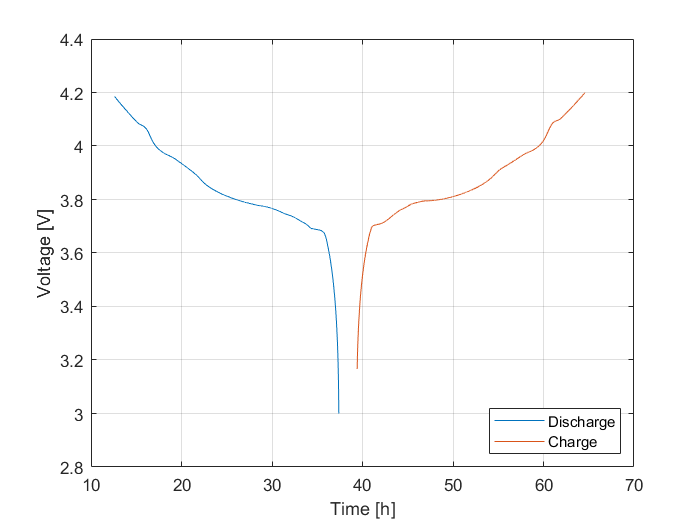

% Split charge and discharge data using step indexes:
POCV_discharge = POCV_GITT_data(POCV_GITT_data.("Step_Index") == 11,:);
POCV_charge = POCV_GITT_data(POCV_GITT_data.("Step_Index") == 13,:);
% 
figure
plot(POCV_discharge.("Test_Time(s)")./3600, POCV_discharge.("Voltage(V)"))
ylabel('Voltage [V]')
xlabel('Time [h]')
hold on
plot(POCV_charge.("Test_Time(s)")./3600, POCV_charge.("Voltage(V)"))
legend('Discharge','Charge',Location='southeast')
grid on

## Galvanostatic Intermittent Titration Technique (GITT)

Git test is used for blablabla....

Andre testing the file using Github...

We can split data using the TC_Counter1.... 

PLOT GITT HERE

[1] Planden, B., Lukow, K. (2021). Battery Test Consortium. Version v0.1.0. Available at: [`https://github.com/Oxford-Brookes-HVES/BTC`](https://github.com/Oxford-Brookes-HVES/BTC) 

`[2] `Plett, G. L. (2015). Battery Management Systems, Volume 1: Battery Modeling.